# Homework_4_Problem_5_62

clear; close; clc;

## Declare variables

% problem variables
P = 50E3; % Load (N)
l = 5.0; % length (m)
E = 210E9; % elastic modulus (Pa)
simga_a = 250E6; % allowable compressive stress (Pa)
rho = 7850; % density (kg/m^3)

% plotting parameters
domain = [-.1, 1];
range = [-.01, .01];
n_pointsPlot = 5000;


## Define plotting variables

% create vector of x and y coordiantes
x_1 = linspace(domain(1), domain(2), floor(sqrt(n_pointsPlot))); 
x_2 = linspace(range(1), range(2), floor(sqrt(n_pointsPlot)));
% convert into 2x2 mesh
[x_1_grid, x_2_grid] = meshgrid(x_1,x_2);

## Plot cost function

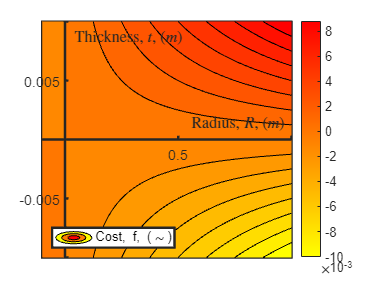

% evaluate cost function
f = x_1_grid.*x_2_grid;

% plot cost function
figure;
contourf(x_1_grid, x_2_grid, f, 15, "LineWidth",.001, "DisplayName","Cost, f, (\sim)"); colormap(flipud(autumn)); colorbar;
hold on;

% make plot look good
xlim(domain); ylim(range);
legend("Location","southwest")
set(gca,"FontSize",12)
set(gca,'BoxStyle','back','Layer','top','XAxisLocation','origin',...
    'YAxisLocation','origin');
set(gca,"LineWidth",2)
xlabel("Radius, $R$, $\left(m\right)$", "Interpreter","latex");
ylabel("Thickness, $t$, $\left(m\right)$", "Interpreter","latex")

## Plot the Contraint functions

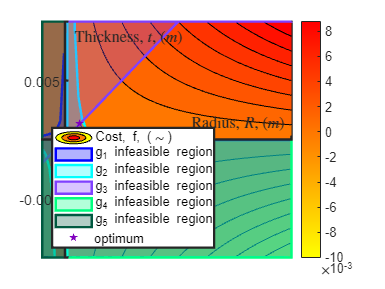

hold on;

% stress constraint
boundaryEdges_Xcoords = [x_1, fliplr(x_1)];
boundaryEdges_Ycoords = [P./(-simga_a*2*pi*x_1), range(1) * ones(size(x_1))];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [0,0,1], "FaceAlpha",.3, "EdgeColor",[0,0,1], "LineWidth",2, "DisplayName","g_1 infeasible region")

% buckling constraint
boundaryEdges_Xcoords = [x_1, fliplr(x_1)];
boundaryEdges_Ycoords = [P./(pi^3*E/(4*l^2)*x_1.^3), range(1) * ones(size(x_1))];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [0,1,1], "FaceAlpha",.3, "EdgeColor",[0,1,1], "LineWidth",2, "DisplayName","g_2 infeasible region")

% dimentions constraint
boundaryEdges_Xcoords = [x_1, fliplr(x_1)];
boundaryEdges_Ycoords = [x_1/50, range(2) * ones(size(x_1))];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [.5,.25,1], "FaceAlpha",.3, "EdgeColor",[.5,.25,1], "LineWidth",2, "DisplayName","g_3 infeasible region")

% non negativity of x_1 constraint
boundaryEdges_Xcoords = [x_1, fliplr(x_1)];
boundaryEdges_Ycoords = [0 * ones(size(x_1)), range(1) * ones(size(x_1))];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [0,1,.5], "FaceAlpha",.3, "EdgeColor",[0,1,.5], "LineWidth",2, "DisplayName","g_4 infeasible region")

% non negativity of x_2 constraint
boundaryEdges_Xcoords = [0 * ones(size(x_1)), domain(1) * ones(size(x_1))];
boundaryEdges_Ycoords = [x_2, fliplr(x_2)];
fill(boundaryEdges_Xcoords, boundaryEdges_Ycoords, [0,.35,.25], "FaceAlpha",.3, "EdgeColor",[0,.35,.25], "LineWidth",2, "DisplayName","g_5 infeasible region")

% % plot the constraint function
% fimplicit(@(x,y) x/y-50, domain, "-", "Color",[.25,.75,.5],"LineWidth",3);

%plot the omptimum
beta = (100*P*l^2/(pi^3*E)).^(1/4); % solution parameter
plot(beta,beta/50,"Marker","pentagram","MarkerSize",6,"MarkerEdgeColor",[.5,0,.75],"MarkerFaceColor",[.5,0,.75],"LineStyle","none", "DisplayName","optimum")




% [v,Lambda] = eigs([8,-5;-5,6])
% fimplicit(@(x,y) x*v(1,1) + y*v(2,1), "-r" , "DisplayName", sprintf("Eig. vect. \\lambda = %g", Lambda(1,1)))
% fimplicit(@(x,y) x*v(1,2) + y*v(2,2), "-b", "DisplayName", sprintf("Eig. vect. \\lambda = %g", Lambda(2,2)))

% A = [8, -5, 1;...
%      6, -5, 1;...
%      1,  1, 0];
% inv(A)
% c = [0;0;4];
% 
% inv(A)*c

%a = fminsearch( @(x,y) 4*x.^2 + 3*y.^2 -5*x.*y, [5,5])


syms x_1 x_2 u_2 u_3 E l pi
eq_u_2 = solve(x_2 - u_2 * 3*pi^3*E/(4*l^2)*x_1^2*x_2 + u_3/x_2, u_2)

$$eq\_u\_2 = \frac{4\,l^{2}\,\left(x_{2}+\frac{u_{3}}{x_{2}}\right)}{3\,\text{E}\,\pi^{3}\,{x_{1}}^{2}\,x_{2}}$$

eq_u_3 = solve(x_1 - u_2 * pi^3*E/(4*l^2)*x_1^3 - u_3*x_1/x_2^2, u_3)

$$eq\_u\_3 = \frac{{x_{2}}^{2}\,\left(x_{1}-\frac{\text{E}\,\pi^{3}\,u_{2}\,{x_{1}}^{3}}{4\,l^{2}}\right)}{x_{1}}$$

eq_u_3 = subs(eq_u_3, u_2, eq_u_2)

$$eq\_u\_3 = \frac{{x_{2}}^{2}\,\left(x_{1}-\frac{x_{1}\,\left(x_{2}+\frac{u_{3}}{x_{2}}\right)}{3\,x_{2}}\right)}{x_{1}}$$

eq_u_3 = solve(u_3 == eq_u_3, u_3)

$$eq\_u\_3 = \frac{{x_{2}}^{2}}{2}$$

eq_u_2 = subs(eq_u_2, u_3, eq_u_3)

$$eq\_u\_2 = \frac{2\,l^{2}}{\text{E}\,\pi^{3}\,{x_{1}}^{2}}$$